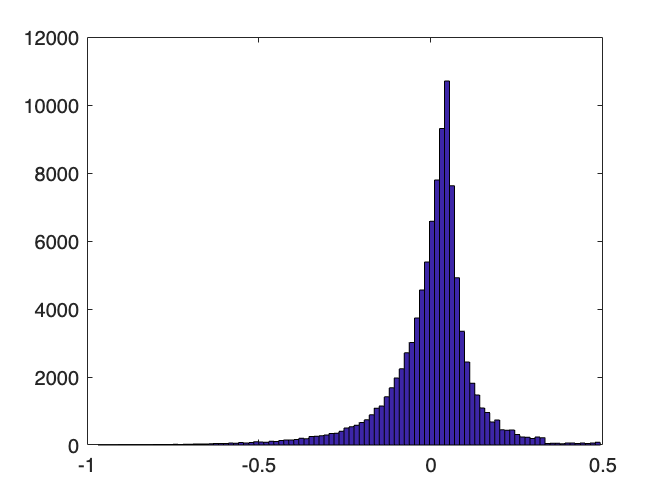

clear
trials = 100000;
percent = .2;
error2 = simulation(trials, 2);
error5 = simulation(trials, 5);
error10 = simulation(trials, 10);
error20 = simulation(trials, 20);


hist(error2,100)

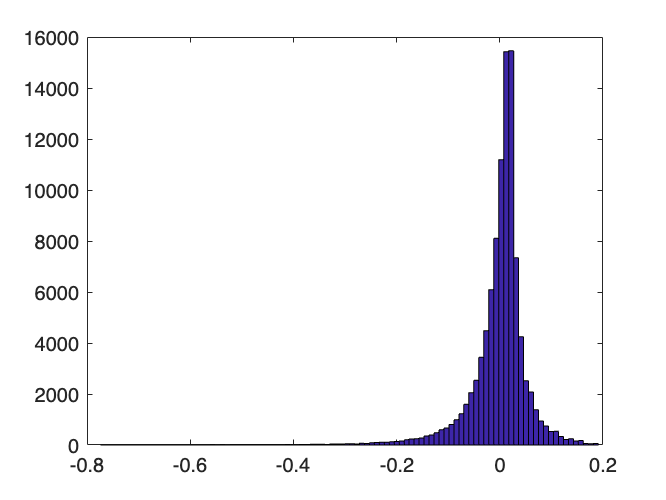

hist(error5,100)

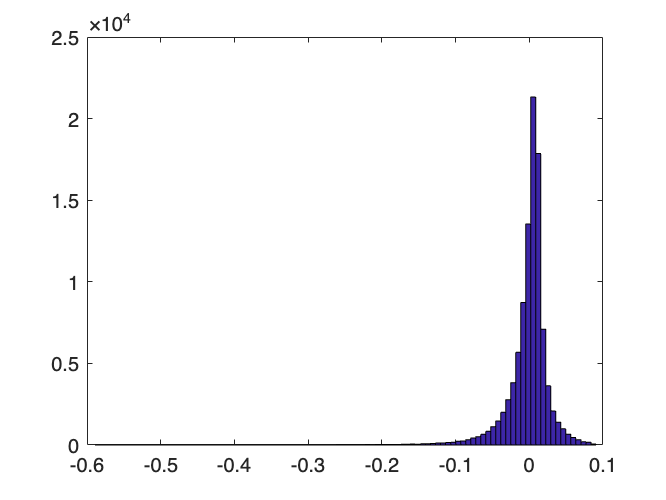

hist(error10,100)

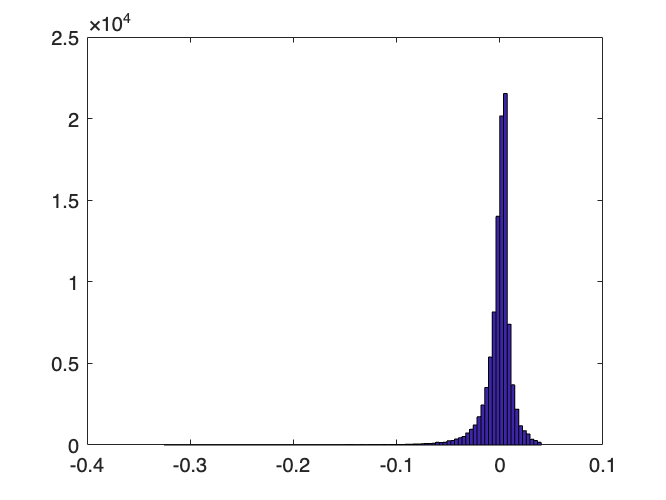

hist(error20,100)


function error = simulation(trials, percent)
    percent = percent/100;
    for i = 1:trials
        N = randi([100, 1000]);
        n = round(percent*N);
        sample = randi([1,N],1,n);
        Npredict = (n+1)/n * max(sample) - 1;
        error(i) = (Npredict - N)/N;
    end
end